# Bode Diagrams in MATLAB

## Motivation

An interesting property of linear systems is that, given a sinusoidal input, the output will (eventually) be a sinusiod with **identical frequency**, but **different amplitude and phase**.

For example, let us study the output of the second-order system


$$H\left(s\right)=\frac{\omega_0^2 }{s^2 +2\zeta \omega_0 \;s+\omega_0^2 }$$


Given a sinusoidal input 

$x\left(t\right)=\cos \left(\omega t\right)$,

with different values of $\omega$.

*[Note:] You'll need to install the ****Signal Processing Toolbox**** to properly run this LiveScript.*

% Housekeeping
clc; clear; close all

% System Parameters
w0 = 20;
z = 0.1;

% Transfer Function
s = tf('s');
H = w0^2/(s^2+2*z*w0*s+w0^2);

We begin by plotting the output response to an input signal that features $\omega \ll \omega_0$.

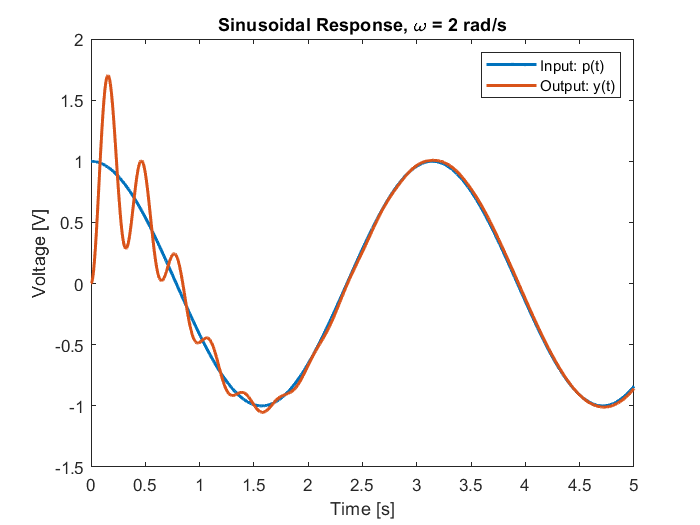

% Input Time Vector
tx = 0:0.001:5;

% Input Frequency
w = w0/10;

% Input Signal
x = cos(w*tx);

% Compute sinusoid response
[y,ty] = lsim(H,x,tx);

% Plot the Response
plot(tx,x,ty,y,'LineWidth',2)
title(['Sinusoidal Response, \omega = ' num2str(w) ' rad/s'])
xlabel('Time [s]')
ylabel('Voltage [V]')
legend('Input: p(t)','Output: y(t)')

After an initial transient ($\approx 2\ldotp 5\;s$) during which the system oscillates for a bit, the output converges to a sinusoid that is practically the same as the input. The same cannot be said when the input frequency is the same as the system's natual frequency, i.e. $\omega =\omega_0$.

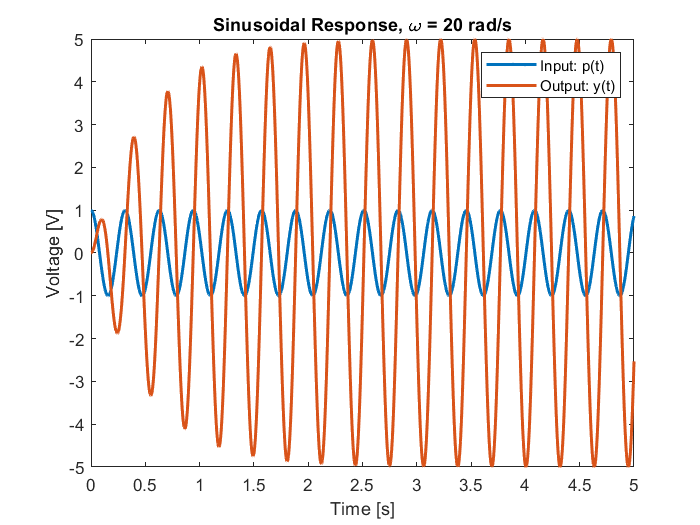

% Input Frequency
w = w0;

% Input Signal
x = cos(w*tx);

% Compute sinusoid response
[y,ty] = lsim(H,x,tx);

% Plot the Response
plot(tx,x,ty,y,'LineWidth',2)
title(['Sinusoidal Response, \omega = ' num2str(w) ' rad/s'])
xlabel('Time [s]')
ylabel('Voltage [V]')
legend('Input: p(t)','Output: y(t)')

After an initial transient ($\approx 2\ldotp 5\;s$), the output converges to a sinusoid that is ${90}^{\mathrm{o}}$ out of phase with the input and $5$ times larger. This is known as the resonant behavior, which is characteristic of systems with complex-conjugate poles. The system has yet another behavior for input signals with a frequency $\omega \gg \omega_0$.

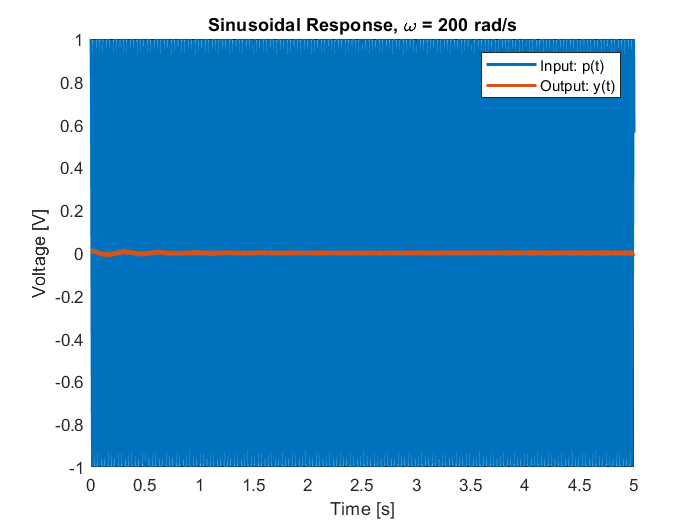

% Input Frequency
w = 10*w0;

% Input Signal
x = cos(w*tx);

% Compute sinusoid response
[y,ty] = lsim(H,x,tx);

% Plot the Response
plot(tx,x,ty,y,'LineWidth',2)
title(['Sinusoidal Response, \omega = ' num2str(w) ' rad/s'])
xlabel('Time [s]')
ylabel('Voltage [V]')
legend('Input: p(t)','Output: y(t)')

For very high frequencies we note that, after a transient, the output converges to a sinusoid that is significantly smaller (in our case, $100$ times smaller) than the input. The objective of Bode diagrams is to provide a snapshot of all the different output behaviors that the system might hve based on the input frequency.

## Scaling Considerations

To draw the bode plot of a system $H\left(s\right)$ using MATLAB, it is sufficient to use the command

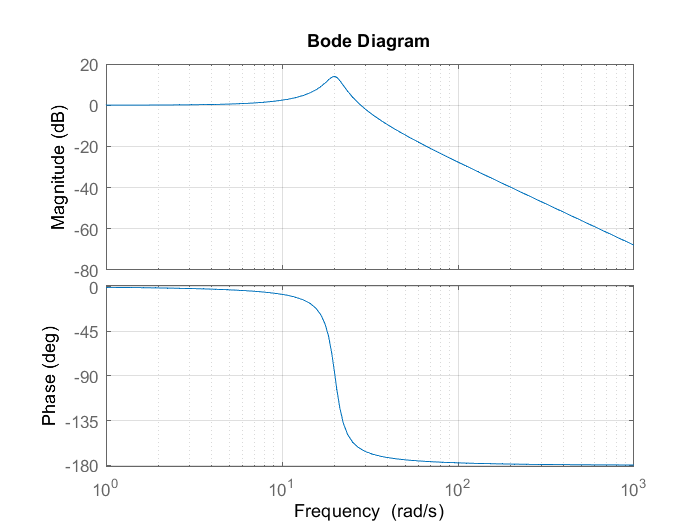

bode(H)
grid on

% Hack from last lecture
pause(0.1)
figure

In this LiveScript, however, we'll store the output data and generate our own plots to have a bit more control over the plotting functions. 

% Compute the magnitude, phase, and frequency points
[mag,phase,w0] = bode(H);

% Reformat the 'mag' and 'phase' into vectors
mag = squeeze(mag);
phase = squeeze(phase);

Having obtained the data, it may seem natural to plot the behavior of the output magnitude as a function of the input frequencty.

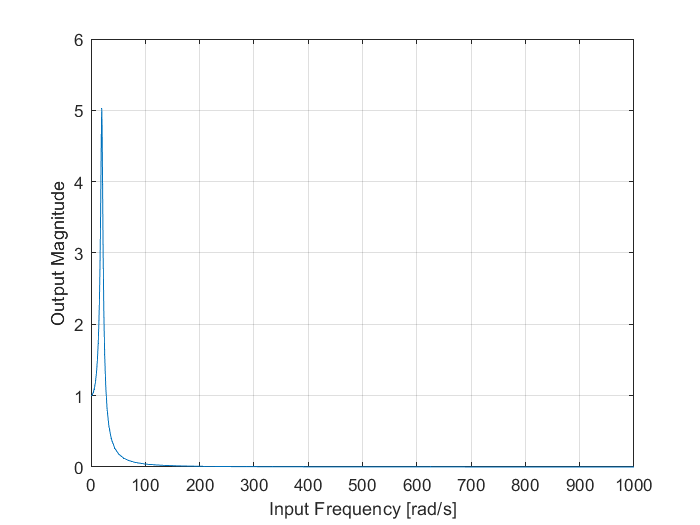

% Standard Plot
plot(w0,mag)
xlabel('Input Frequency [rad/s]')
ylabel('Output Magnitude')
grid on

This plot technically has all the information we need, but is difficult to read since we are interested in the behavior for very high ($\omega =1000\;\mathrm{rad}/s$) and very low ($\omega =1\;\mathrm{rad}/s$) frequencies. Using a linear scale on the $x$ axis causes the low frequency information to be "squished" all the way to the left. This can be solved by using a **logarithmic** scaling on the $x$ axis, which gives equal importance to very low and very high values of $\omega$.

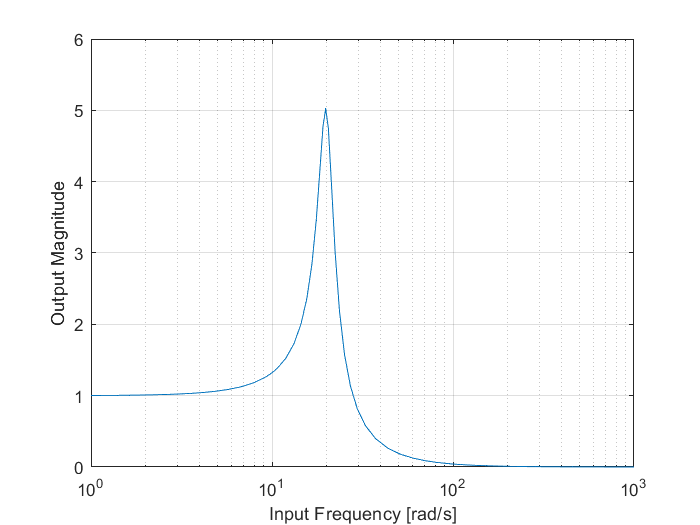

% Logarithmic scaling on the x-axis
semilogx(w0,mag)
xlabel('Input Frequency [rad/s]')
ylabel('Output Magnitude')
grid on

This scaling makes it easier to extract frequency information. However, we now have a similar scaling issue on the magnitude which goes from 1 to 5 and then down to "very small" numbers, which are once again hard to read. To solve this issue, we'll rescale the $y$ axis using the *deciBel *scale.

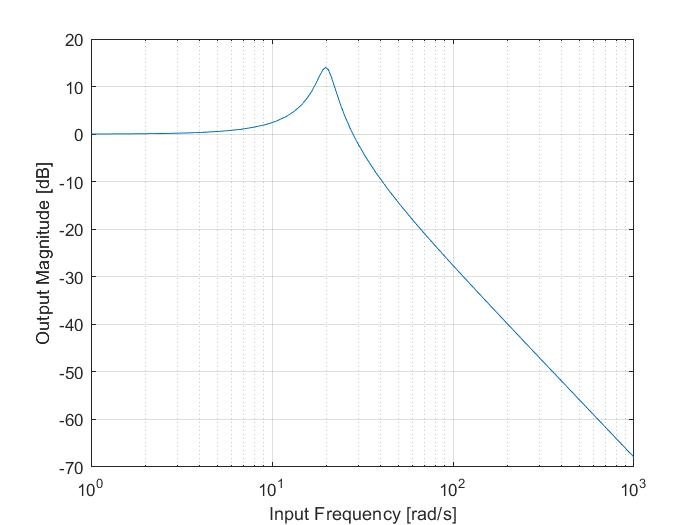

% Bode Diagram of the Magnitude
semilogx(w0,db(mag))
xlabel('Input Frequency [rad/s]')
ylabel('Output Magnitude [dB]')
grid on

This plot makes it easier to find where the output is 10 times smaller (-20 dB), 100 times smaller  (-40 dB), and 1000 times smaller  (-60 dB) than the input. We can also plot the phase of the output using logarithmic scaling on the $x$-axis.

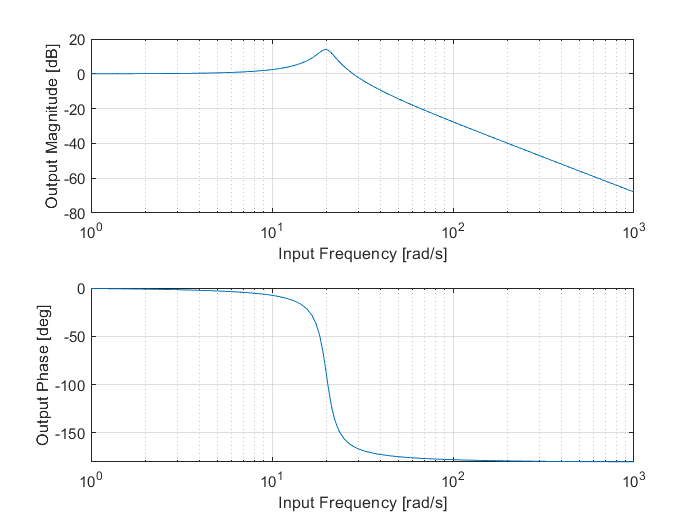

% Bode Diagram
subplot(2,1,1)
semilogx(w0,db(mag))
xlabel('Input Frequency [rad/s]')
ylabel('Output Magnitude [dB]')
ylim([-80 20])
grid on

subplot(2,1,2)
semilogx(w0,phase)
xlabel('Input Frequency [rad/s]')
ylabel('Output Phase [deg]')
ylim([-180 0])
grid on

This plot is fundamentally the same as the one we obtained by just using the command

`bode(H)`

## Frequency Response

We now show an animation of how the output of the system changes based on the frequency of the input.

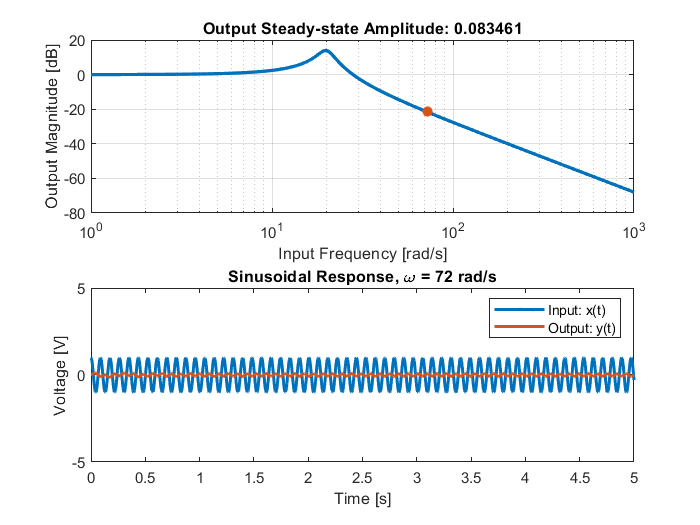

figure
for wval = [1:.2:30 32:2:200]
    x = cos(wval*tx); 
    
    % Compute the sinusoial response
    [y,ty] = lsim(H,x,tx);
    
    % Compute magnitude from Bode
    [magw,~]=bode(H,wval);
    
    % Bode Diagram
    subplot(2,1,1)
    semilogx(w0,db(mag),wval,db(magw),'*','LineWidth',2)
    title(['Output Steady-state Amplitude: ' num2str(magw)])
    xlabel('Input Frequency [rad/s]')
    ylabel('Output Magnitude [dB]')
    ylim([-80 20])
    grid on
    
    % Plot the Response
    subplot(2,1,2)
    plot(tx,x,ty,y,'LineWidth',2)
    title(['Sinusoidal Response, \omega = ' num2str(wval) ' rad/s'])
    xlabel('Time [s]')
    ylabel('Voltage [V]')
    ylim([-5 5])
    legend('Input: x(t)','Output: y(t)')
    pause(0.1)
end